clear
load 3UAV_6users/PartA.mat

A_init = sol.A;
P_init;
Q_init;
global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

obj = TrajectoryOptimization(A_init, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower, d_min);
obj

obj = 1.7116

Q = optimvar('Q', M,2,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 2000);

[f, speed_constraint, initial_final, inter_uav_distance] = fcn2optimexpr(@TrajectoryOptimization,A_init, P_init, Q, K, M, N, Rho0, H, W, NoisePower, d_min);
f;

problem2 = optimproblem('ObjectiveSense', 'max');
problem2.Objective = f;

options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 50000, 'OptimalityTolerance', 1.0000e-07, "Algorithm","interior-point", "StepTolerance",0);

deltaT = T/N;
Max_Dist = deltaT * Vmax

Max_Dist = 70

problem2.Constraints.speed = speed_constraint <= Max_Dist;
problem2.Constraints.repeat = initial_final <= 200;
problem2.Constraints.inter_uav_distance = inter_uav_distance == 1;

show(problem2)


  OptimizationProblem : 

	Solve for:
       Q

	maximize :
       [argout,~,~,~] = TrajectoryOptimization(extraParams{1}, extraParams{2}, Q, 6, 3, 150, 1e-06, 100, extraParams{3}, 1e-14, 100)

       

x1.Q = Q_init;


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     901   -1.711627e+00    0.000e+00    1.426e-05


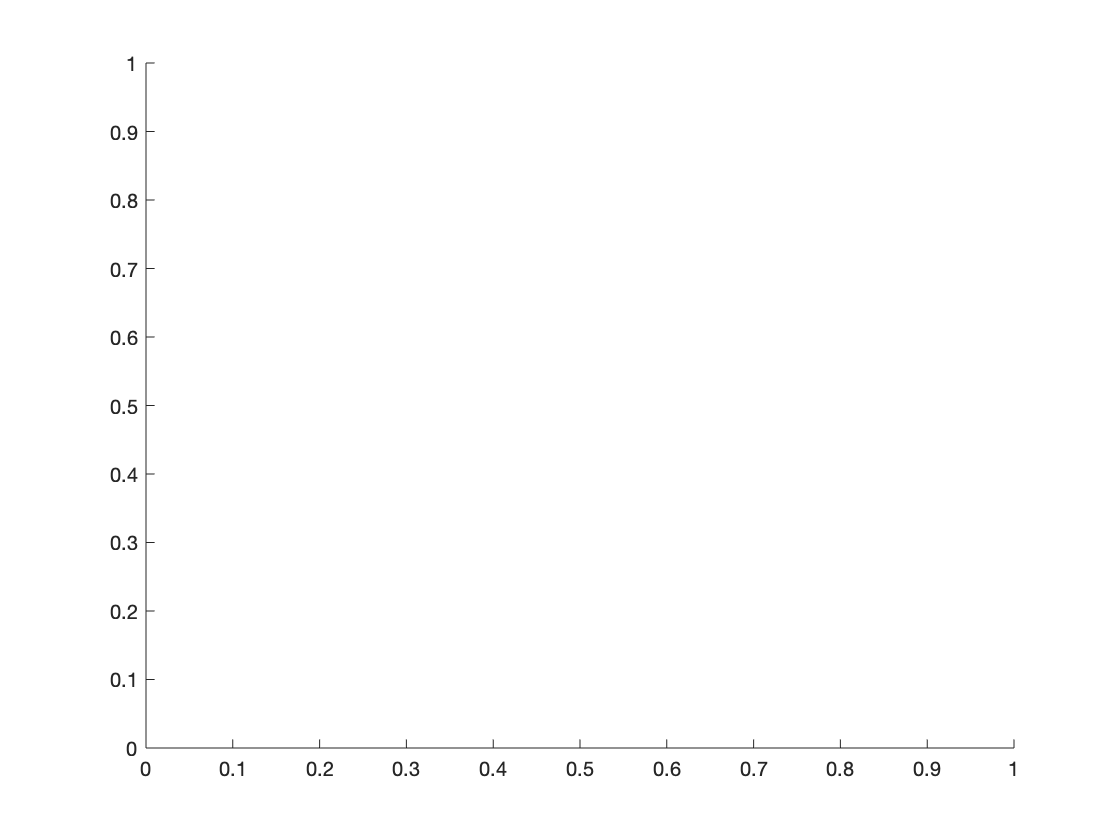

    1    1854   -1.711627e+00    0.000e+00    1.426e-05    2.528e-11
    2    2756   -1.711627e+00    0.000e+00    1.424e-05    2.150e-04
    3    3658   -1.711627e+00    0.000e+00    1.424e-05    1.075e-03
    4    4560   -1.711629e+00    0.000e+00    1.424e-05    5.375e-03
    5    5462   -1.711634e+00    0.000e+00    1.424e-05    2.688e-02
    6    6364   -1.711663e+00    0.000e+00    1.424e-05    1.344e-01
    7    7266   -1.711808e+00    0.000e+00    1.424e-05    6.719e-01
    8    8168   -1.712530e+00    0.000e+00    1.424e-05    3.359e+00
    9    9070   -1.716139e+00    0.000e+00    1.421e-05    1.679e+01
   10    9972   -1.734058e+00    0.000e+00    1.410e-05    8.382e+01
   11   10874   -1.818662e+00    0.000e+00    1.373e-05    4.151e+02
   12   11776   -1.957106e+00    0.000e+00    1.393e-05    1.870e+03
   13   12678   -1.968682e+00    0.000e+00    1.257e-05    4.026e+02
   14   13580   -1.968719e+00    0.000e+00    1.239e-05    3.154e+01
   15   14482   -1.968722e+00    0

[sol2, fval2, exitflag2, output2] = solve(problem2, x1, 'Options', options);

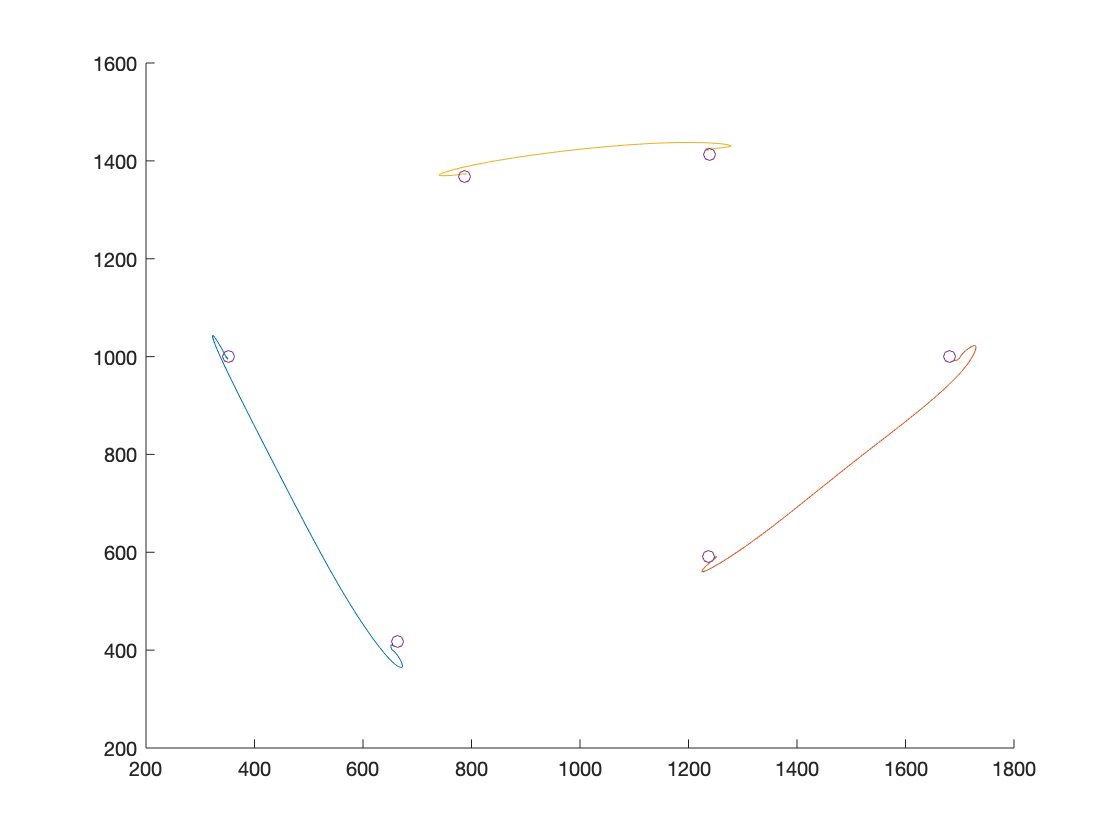

Q2 = sol2.Q;
%Q2 = Q_init;
Xs = Q2(:, 1, :);
Ys = Q2(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off

clf
